# SISTEMAS DE CONTROL II

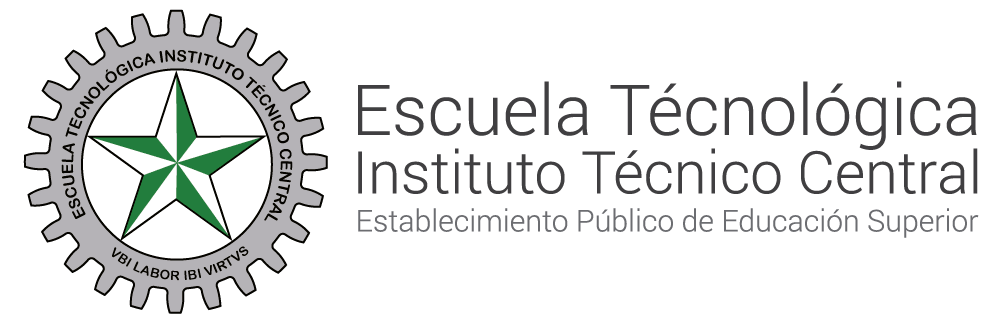

# Lugar Geometrico de las Raices

**Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

**Coautor: David Hassan Jaramillo Avendaño**

## ¿Que es un polo y un cero?

Un [polo](https://la.mathworks.com/help/control/ref/dynamicsystem.pole.html) en una función de transferencia es la raíz del denominador de una función. Los polos de un sistema dinámico determinan su estabilidad y respuesta. 

Estos polos ayudan a determinar que tan estable, con respecto al tiempo, puede ser un sistema, al igual que nos pueden ayudar a darle una estabilidad donde pueda ser conveniente en el diseño de sistemas de control. 

Los ceros y los polos se encuentran en el plano complejo $S$. Cuando $S$ tiende a un cero, el polinomio del numerador de la función de transferencia tiende a cero, por lo que la función de transferencia también tiende a cero.

Si la función de transferencia es cero, probablemente significa que no hay respuesta de frecuencia ni de tiempo. Esto sería similar a aplicar cero voltios de CC en un circuito. 

#### ¿Como obtener los polos?

Vamos a tomar como ejemplo la siguiente funcion de transferencia en el dominio de $S$:


$$G\left(s\right)=1+\frac{k\left(s+3\right)}{s\left(s+5\right)\left(s+6\right)\left(s^2 +2s+2\right)}$$


resolviendo el denominador queda: $s^5 +13s^4 +54s^3 +82s^2 +60s$

clear workspace
clc
numerador = [1, 3];   % Numerador del sistema (no olvidar que el numero mas a la derecha no lleva s ejemplo s^2+5s+3 quedaria aqui escrito (1 5 3) solo anotamos los numeros que acompañan a s) 
denominador = [1, 13, 54, 82, 60, 0];   % Denominador del sistema al no haber ningun numero entero sin variable colocamos 0 de ultimo termino para hacer entender al sistema que el penultimo termino esta multiplicado por s^1
fprintf('*** Función de Transferencia ***\n');

*** Función de Transferencia ***



sistema = tf(numerador, denominador)


sistema =
 
                  s + 3
  -------------------------------------
  s^5 + 13 s^4 + 54 s^3 + 82 s^2 + 60 s
 
Continuous-time transfer function.
Model Properties


Para hallar los polos en esta funciones podemos comenzar igualando cada termino (parentesis) a cero:

$s=0\;$         primer cero

$s=-5$       segundo cero

$s=-6$       tercer termino

para el cuadrado $\left(s^2 +2s+2\right)$ usamos la formula cuadratica 


$$\frac{-b\pm \sqrt{{\left(b\right)}^2 -4*a*c}}{2*a}$$


por lo que nos quedan las siguientes raices:


$$s=-1+1i$$



$$s=-1-1i$$


Ubicando estos puntos en el plano complejo nos daria de la siguiente forma:

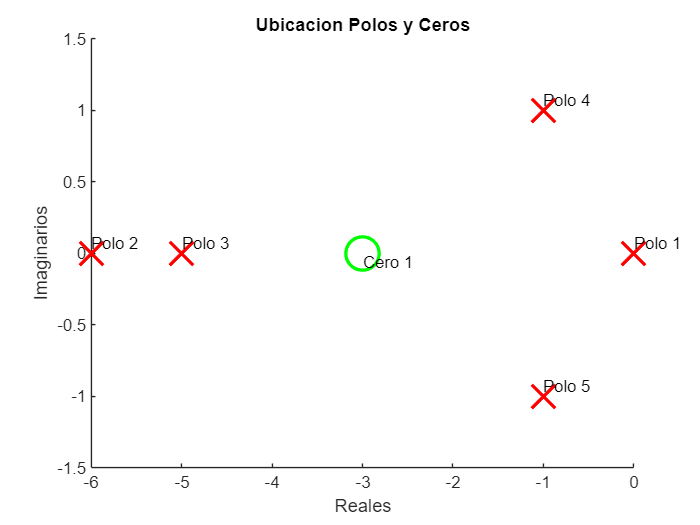


polos = pole(sistema); %Calculo de polos de la funcion de transferencia
ceros = zero(sistema); %Calculo de ceros de la funcion de trasnferencia

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

xlabel('Reales');
ylabel('Imaginarios');

title('Ubicacion Polos y Ceros');

Entendiendo esto pasaremos a lo que nos interesa.

## ¿Como Hallar el Lugar Geometrico de las Raices (LGR)?

Antes que nada, ¿Que es el Lugar Geometrico de las Raices?.

El Lugar Geométrico de las Raíces (LGR) es una técnica gráfica en el análisis de sistemas de control que muestra cómo los polos de un sistema de lazo cerrado se mueven en el plano complejo cuando se varía un parámetro, generalmente la ganancia K. Este enfoque es crucial porque los polos determinan la estabilidad y el comportamiento dinámico del sistema, como la rapidez de la respuesta y las oscilaciones. Para que un sistema sea estable, sus polos deben ubicarse en el semiplano izquierdo del plano complejo, es decir, con partes reales negativas.

Ahora si, teniendo un poco mas claro haremos el paso a paso de como se halla el LGR:

#### Paso 1

Lo primero es entender que tenemos una expresion de la forma 


$$1+G\left(s\right)=0$$


En donde $G\left(s\right)$es una funcion de transferencia multiplicado por $K$, donde $K$es la ganancia del sistema haciendo que sea estable este.


$$1+G\left(s\right)=1+K\frac{F\left(s\right)}{D\left(s\right)}=0$$


entendiendo esto necesitamos dejaremos todo lineal sin fracciones en lo posible para quedar un solo polinomio y con esto podremos resolver varios pasos siguientes.

#### Ejemplo

Con la siguiente funcion de transferencia abordaremos todos los pasos para resolver los LGR.

clear workspace
clc
numerador = [1, 3];   % Numerador del sistema (no olvidar que el numero mas a la derecha no lleva s ejemplo s^2+5s+3 quedaria aqui escrito (1 5 3) solo anotamos los numeros que acompañan a s) 
denominador = [1, 13, 54, 82, 60, 0];   % Denominador del sistema al no haber ningun numero entero sin variable colocamos 0 de ultimo termino para hacer entender al sistema que el penultimo termino esta multiplicado por s^1
fprintf('*** Función de Transferencia ***\n');

*** Función de Transferencia ***



sistema = tf(numerador, denominador)


sistema =
 
                  s + 3
  -------------------------------------
  s^5 + 13 s^4 + 54 s^3 + 82 s^2 + 60 s
 
Continuous-time transfer function.
Model Properties



$$G\left(s\right)=1+\frac{k\left(s+3\right)}{s\left(s+5\right)\left(s+6\right)\left(s^2 +2s+2\right)}$$


resolviendo la suma e igualando a 0 la ecuacion podemos decir que el resultado es el siguiente


$$G\left(s\right)=\frac{\left(s^5 +13s^4 +{54s}^3 +82s^2 +60s+\textrm{ks}+3k\right)}{s^5 +13s^4 +{54s}^3 +82s^2 +60s}=0$$


pasamos el denominador al lado derecho asi lo podemos anular a conveniencia y dejar un solo polinomio que contenga $K$por lo que queda:


$$G\left(s\right)=s^5 +13s^4 +{54s}^3 +82s^2 +60s+\textrm{ks}+3k$$


### Paso 2

Lo siguiente es encontrar en la primera funcion de transferencia los polos y ceros y graficarlos (como se hizo el primer punto de este documento) para entender un poco mejor donde estan ubicados en el plano complejo, esto con la intencion de entender como se podra comportar el sistema si va a ser estable o inestable.

***Dirigirse al primer apartado***

fprintf('*** Calcular ceros del sistema ***\n');

*** Calcular ceros del sistema ***


ceros = zero(sistema)

ceros = -3

fprintf('*** Calcular polos del sistema ***\n');

*** Calcular polos del sistema ***


polos = pole(sistema)

polos =    0.0000 + 0.0000i
  -6.0000 + 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


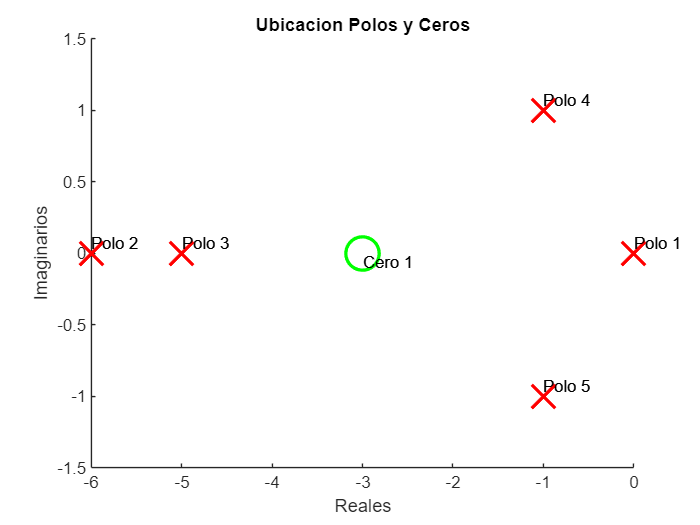

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

xlabel('Reales');
ylabel('Imaginarios');

title('Ubicacion Polos y Ceros');

### Paso 3

Teniendo los polos y ceros podemos calcular la cantidad de ramificaciones que tiene el sistema entonces para ello tenemos en cuenta que $n=\textrm{polos}$ y $m=\textrm{ceros}$. Osea son la cantidad de polos que salieron digamos:

Una funcion de transferencia donde tengo n_cantidad de polos, no es la sumatoria de ellos si no a la relacion de cantidad entonces un ejemplo seria un polinomio: $s^2 +\left(0\ldotp 15k-1\ldotp 5\right)s+1$ sus raices respectivamente serian $=0\ldotp 75\pm 0\ldotp 6614i$ en este caso salieron dos raices, esta cantidad es a la que se refiere $n=\textrm{polos}$, esto aplica igualmente a los ceros.

Entonces volviendo al problema que veniamos resolviendo tenemos que $n=5\;\left(\textrm{cantidad}\;\textrm{de}\;\textrm{polos}\right)$  y $m=1\;\left(\textrm{cantidad}\;\textrm{de}\;\textrm{ceros}\right)$

por lo que la cantidad de ramas es la diferencia entre polos y ceros:


$$n-m\;=\;5-1=\;4$$


¿Pero a que hace referencia estas ramificaciones en los sistemas de control?¿Que quiere decir ese "4"?.

En el LGR, la diferencia n−m es importante porque determina el número de ramas y la forma en que estas se comportan en el plano complejo. Las ramas del LGR, que representan cómo se mueven los polos al variar la ganancia K, comienzan en los polos y terminan en los ceros; si n>m, hay n−m ramas que se extienden hacia el infinito. Esta diferencia también influye en las asíntotas que indican hacia dónde se dirigen las ramas en el infinito, afectando la estabilidad y el comportamiento general del sistema en el LGR.

### Paso 4

Una vez hallado las ramificaciones podemos encontrar las asintotas. 

La formula nos dice que es :


$$\frac{180\left(2N+1\right)}{n-m}$$


por lo que al remplazar la iteracion de N


$$\frac{180\left(2N+1\right)}{5-1}\to \frac{180\left(2\left(0\right)+1\right)}{4}=45\degree \to \textrm{primera}\;\textrm{asintota}$$


y asi vamos haciendo la iteracion de N hasta 4

N =4;
Valores_asintotas = (180 * (2 * N + 1)) / 2

Valores_asintotas = 810

fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos)

n_polos = 5

fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros)

n_ceros = 1

n_asintotas = n_polos - n_ceros

n_asintotas = 4


% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


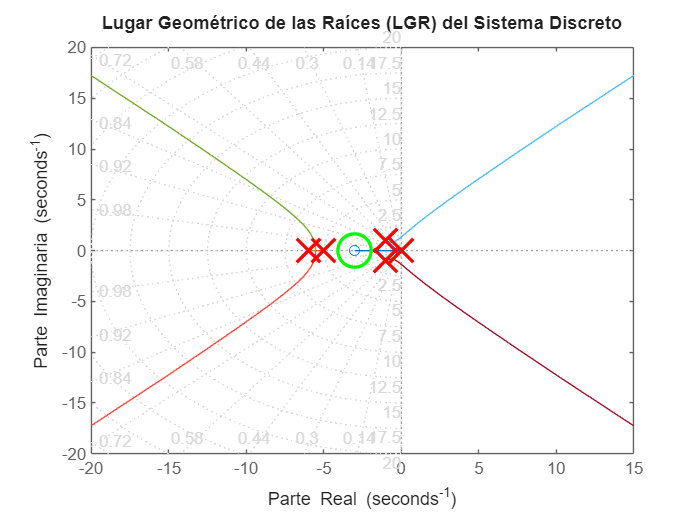

figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

Estas asintotas nos explican hacia donde tiende la ganancia $K$por lo que es bastante importante para saber desde dondce hasta donde podemos llegar con la ganancia.

### Paso 5

Seguido hallaremos el centroide, este es el punto donde se interseccionan las asintotas y queda exactamente sobre el eje real. El centroide no es una raiz del sistema si no es solo un punto que nos muestra como se distribuyen las ramas de LGR que se dirigen hasta el infinito para ello tenemos una formula donde es la sumatoria de los polores solo la parte real y lo ceros tambien su parte real si lo corresponde.


$$\textrm{Centroide}=\frac{\Sigma n-\Sigma m}{n-m}$$


polos = pole(sistema)

polos =    0.0000 + 0.0000i
  -6.0000 + 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


ceros = zero(sistema)

ceros = -3


$$\textrm{Centroide}=\frac{\left(0+\left(-6\right)+\left(-5\right)+\left(-1\right)+\left(-1\right)\right)-\left(-3\right)}{5-1}\to \frac{-13+3}{4}\to -\frac{10}{4}=-2\ldotp 5$$


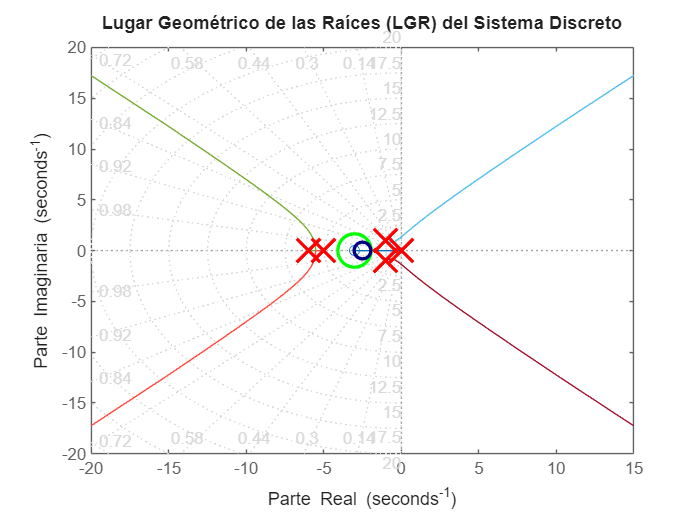

figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)
centroide = (sum(real(polos)) - sum(real(ceros))) / (n_polos- n_ceros); % Centroide en el eje real


for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

plot(centroide, 0, 'o', 'MarkerSize', 10, 'LineWidth', 2, 'Color', [0, 0, 0.5]); % Centroide en azul oscuro
text(centroide + 0.5, 0, sprintf('Centroide: %.2f', centroide), 'FontSize', 10, 'Color', [0, 0, 0.5]); % Texto

fprintf('*** Graficar el lugar geométrico de las raíces ***\n');

*** Graficar el lugar geométrico de las raíces ***


figure;
rlocus(sistema,k); 
ganancia = (0:1:35.5);
[r, k1]=rlocus(sistema,ganancia)

r =    0.0000 + 0.0000i  -0.0528 + 0.0000i  -0.1122 + 0.0000i  -0.1804 + 0.0000i  -0.2604 + 0.0000i  -0.3568 + 0.0000i  -0.4751 + 0.0000i  -0.6163 + 0.0000i  -0.7639 + 0.0000i  -0.8940 + 0.0000i  -1.0000 + 0.0000i  -1.0865 + 0.0000i  -1.1589 + 0.0000i  -1.2210 + 0.0000i  -1.2754 + 0.0000i  -1.3238 + 0.0000i  -1.3675 + 0.0000i  -1.4074 + 0.0000i  -1.4440 + 0.0000i  -1.4780 + 0.0000i  -1.5097 + 0.0000i  -1.5393 + 0.0000i  -1.5672 + 0.0000i  -1.5936 + 0.0000i  -1.6186 + 0.0000i  -1.6423 + 0.0000i  -1.6649 + 0.0000i  -1.6865 + 0.0000i  -1.7072 + 0.0000i  -1.7270 + 0.0000i  -1.7460 + 0.0000i  -1.7643 + 0.0000i  -1.7819 + 0.0000i  -1.7990 + 0.0000i  -1.8154 + 0.0000i  -1.8313 + 0.0000i
  -6.0000 + 0.0000i  -5.9803 + 0.0000i  -5.9596 + 0.0000i  -5.9376 + 0.0000i  -5.9143 + 0.0000i  -5.8892 + 0.0000i  -5.8621 + 0.0000i  -5.8323 + 0.0000i  -5.7988 + 0.0000i  -5.7602 + 0.0000i  -5.7131 + 0.0000i  -5.6478 + 0.0000i  -5.5264 + 0.0774i  -5.5286 + 0.1651i  -5.5309 + 0.2202i  -5.5331 + 0.2640i  -5.53

k1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


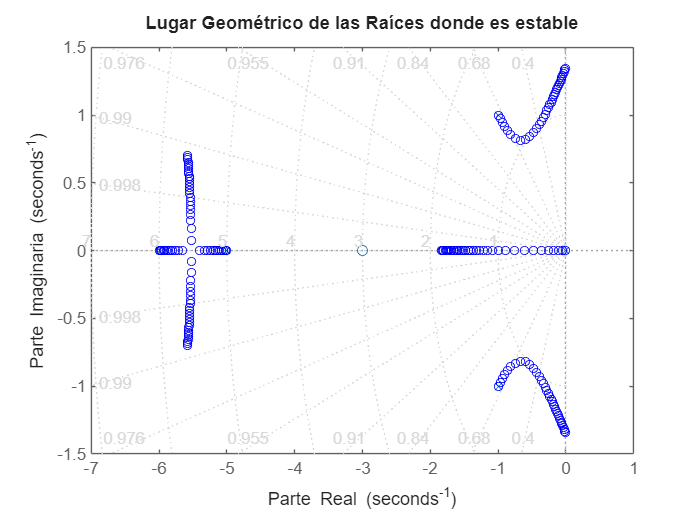

title('Lugar Geométrico de las Raíces donde es estable');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
hold on
for i = 1:length(ganancia)
    % Graficar cada raíz correspondiente al valor de ganancia 'k(i)'
    plot(real(r(:, i)), imag(r(:, i)), 'bo', 'MarkerSize', 5, 'DisplayName', sprintf('k = %.1f', ganancia(i)));
end
grid on;

### Paso 6

Por ultimo hallaremos en que punto K hace que nuestro sistema es estable, para ello usaremos el criterio de Routh Hurwitz.


syms a0 a1 a2 a3 b1 b2 b3 c1 c2 d1 d2 e1 f1 g h


tabla_routh = [a3, a2, a1, a0;  
               b3, b2, b1, 0;  
               c2, c1, 0, 0;  
               d2, d1, 0, 0;
               e1, 0, 0, 0;
               f1, 0, 0, 0]; 


tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

           Columna_1    Columna_2    Columna_3    Columna_4
           _________    _________    _________    _________

    s^5       a3           a2           a1           a0    
    s^4       b3           b2           b1           0     
    s^3       c2           c1           0            0     
    s^2       d2           d1           0            0     
    s^1       e1           0            0            0     
    s^0       f1           0            0            0     



Esta tabla nos esxplica como deben ir ubicada todos datos del sistema, pero... ¿Cual ecuacion debemos usar aqui?, en el paso 1 hicimos una simplificación: 


$$G\left(s\right)=s^5 +13s^4 +{54s}^3 +82s^2 +60s+\textrm{ks}+3k$$


Para ponerlo snecesitamos declarar los coeficientes que acompañan cada uno de las s:

s^5 = 1, s^4 = 13, s^3 = 54, s^2 = 82, s^1 = 60+k, s^0 = 3k

ahora podemos remplazar estos valores en la tabla por lo que queda de la siguiente forma.

syms a0 k b1 c1 d1 e1 


tabla_routh = [1, 54, 60+k, a0;  
               13, 82, 3*k, 0;
               b1, b2, 0, 0;  
               c1, c2, 0, 0;
               d1, 0, 0, 0;
               e1, 0, 0, 0]; 


tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

           Columna_1    Columna_2    Columna_3    Columna_4
           _________    _________    _________    _________

    s^5       1            54         k + 60         a0    
    s^4       13           82         3*k            0     
    s^3       b1           b2         0              0     
    s^2       c1           c2         0              0     
    s^1       d1           0          0              0     
    s^0       e1           0          0              0     



ahora hallaremos cada variable que esta en la tabla para poder hallar en que momento la ganancia se hace estable para el sistema K.

Empezamos con b1 y b2:

Usaremos matrices para hallar b1 y b2:

Para $\textrm{b1}=\left\lbrack \begin{array}{cc}
1 & 54\\
13 & 82
\end{array}\right\rbrack =\frac{\left(13*54\right)-\left(1*82\right)}{13}=\frac{620}{13}$

Como podemos ver la columna 1 siempre estara fija en nuestra nueva matris y luego usamos la columna dos para completar esta matriz 2*2 para hallar b2 usamos la columna 3.

Para $\textrm{b2}=\left\lbrack \begin{array}{cc}
1 & k+60\\
13 & 3k
\end{array}\right\rbrack =\frac{\left(13*\left(60+k\right)\right)-\left(1*\left(3k\right)\right)}{13}=60+\frac{10}{13}k$ las matrices como comunmente se hace al contrario, para este caso se hace inverso a la matriz que conocemos comunmente por lo que la diagonal principal queda negativa y la segunda queda positiva que es caso contrario de las matrices comúnes.

ahora remplazando en la tabla queda así. 

syms a0 k b1 c1 d1 e1 


tabla_routh = [1, 54, 60+k, a0;  
               13, 82, 3*k, 0;
               620/13, 60+((10/13)*k), 0, 0;  
               c1, c2, 0, 0;
               d1, 0, 0, 0;
               e1, 0, 0, 0]; 


tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

           Columna_1      Columna_2       Columna_3    Columna_4
           _________    ______________    _________    _________

    s^5     1           54                 k + 60         a0    
    s^4     13          82                 3*k            0     
    s^3     620/13      (10*k)/13 + 60     0              0     
    s^2     c1          c2                 0              0     
    s^1     d1          0                  0              0     
    s^0     e1          0                  0              0     



Sabiendo como es el procedimiento remplacemos cada uno de los valores que faltan.

syms a0 k 


tabla_routh = [1, 54, 60+k, a0;  
               13, 82, 3*k, 0;
               620/13, 60+((10/13)*k), 0, 0;  
               (13*k+4070)/62, 3*k, 0, 0;
               (10*(-(k^2)-652*k+24420))/((-13*k)+4070), 0, 0, 0;
               3*k, 0, 0, 0]; 


tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

                          Columna_1                      Columna_2       Columna_3    Columna_4
           ________________________________________    ______________    _________    _________

    s^5    1                                           54                 k + 60         a0    
    s^4    13                                          82                 3*k            0     
    s^3    620/13                                      (10*k)/13 + 60     0              0     
    s^2    (13*k)/62 + 2035/31                         3*k                0              0     
    s^1    (10*k^2 + 6520*k - 244200)/(13*k - 4070)    0                  0              0     
    s^0    3*k                                         0                  0              

Teniendo el ultimo valor de la matriz podemos empezar a hallar los valore donde K hace al sistema estable.

### Paso 7 

Como penultimo paso, hay que verificar que los valores de la primera columna sean positivos. Si todos los valores de esta columna son positivos podemos concluir que $K>0$.

syms a0 k c1 d1 e1 


tabla_routh = [1, 54, 60+k, a0;  
               13, 82, 3*k, 0;
               620/13, 60+((10/13)*k), 0, 0;  
               (13*k+4070)/62, 3*k, 0, 0;
               (10*(-(k^2)-652*k+24420))/((-13*k)+4070), 0, 0, 0;
               3*k, 0, 0, 0]; 


tabla = array2table(tabla_routh, ...
    'VariableNames', {'Columna_1', 'Columna_2', 'Columna_3','Columna_4'}, ...
    'RowNames', {'s^5', 's^4', 's^3', 's^2','s^1','s^0'});
disp(tabla);

                          Columna_1                      Columna_2       Columna_3    Columna_4
           ________________________________________    ______________    _________    _________

    s^5    1                                           54                 k + 60         a0    
    s^4    13                                          82                 3*k            0     
    s^3    620/13                                      (10*k)/13 + 60     0              0     
    s^2    (13*k)/62 + 2035/31                         3*k                0              0     
    s^1    (10*k^2 + 6520*k - 244200)/(13*k - 4070)    0                  0              0     
    s^0    3*k                                         0                  0              

Teniendo el concepto claro del porque es mayor a 0 hacemos la desiggualdad con el valor de $S^0$.


$$3k>0$$


Resolvemos esta desigualdad tenemos que:


$$k>0$$


Pasamos al dato anterior de la fila $S^1$ en la primera columna y hacemos la misma desigualdad:


$$\frac{-10\left(k^2 -652k+24420\right)}{\left(-13k+4070\right)}>0$$


Para poder dejar el termino lo mas facil de resolver podemos pasar lo que esta dividiendo a multiplicar al otro lado por lo que queda:


$$-10\left(k^2 -652k+24420\right)>0\to -10k^2 -6520k+244200$$


Podemos hallar las raices de este polinomio para saber que valores de $K$ pueden hacer estable nuestro sistema. Como en un sistema cuadratico podemos resolverlo con la ecuacion:


$$\frac{-b\pm \sqrt{b^2 -4*a*c}}{2*a}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;a=-10\;\;\;\;\;b=-6520\;\;\;\;\;c=244200$$
 


$$\frac{-\left(-10\right)\pm \sqrt{{\left(-10\right)}^2 -4*\left(-10\right)*244200}}{2*\left(-10\right)}\to \frac{-\left(-10\right)\pm 10\sqrt{97681}}{-20}$$


Resolviendo toda esta ecuacion nos da que K cuando la raiz es positiva 


$$K=-687,52\ldotp \ldotp \ldotp \ldotp$$


Y cuando la raiz es negativa 

 
$$K=35,52\ldotp \ldotp \ldotp \ldotp$$


Cuando $K>0$ el sistema se vuelve inestable por lo que el unico valor que nos sirve es $K=35,52\ldotp \ldotp \ldotp$ esta desigualdad nos dice que el sistema sera unicamente estable cuando las ganancias sean $0<K<35,52\ldotp \ldotp \ldotp$

Si seguimos hayando $K$en el anterior valor osea ${\mathit{\mathbf{S}}}^2$y hacemos su desigualdad, osea: $\frac{-13k+4070}{62}>0$, resolviendo da que $K=\frac{4070}{13}=313,07\ldotp \ldotp \ldotp$

Este valor es mayor a $K=35,52$ por lo que es un valor que no nos sirve para hacer el sistema estable. 

### Resultado

Hay que recordar que la ecuacion que nos estan entregando es:


$$G\left(s\right)=1+\frac{k\left(s+3\right)}{s\left(s+5\right)\left(s+6\right)\left(s^2 +2s+2\right)}$$
 

por lo que para poder graficar esta respuesta hay que resolver todo este termino.

K =1

K = 1


% Numerador: K(s+3)
numerador = [K 3*K];

% Denominador: (s + 5)(s + 6)(s^2 + 2s + 2)(s + 3)
denominador = conv([1, 5], [1, 6]);  % (s + 5)(s + 6)
denominador = conv(denominador, [1, 2, 2]);  % (s^2 + 2s + 2)
denominador = conv(denominador, [1,0]); 

fprintf('*** Funcion de transferencia  ***\n');

*** Funcion de transferencia  ***


sys = tf(numerador, denominador)/(1+tf(numerador, denominador)) %Aqui se hace la suma 1 + G(s) para poder obtener la respuesta del sistema al escalon unitario


sys =
 
                           s^6 + 16 s^5 + 93 s^4 + 244 s^3 + 306 s^2 + 180 s
  ----------------------------------------------------------------------------------------------------
  s^10 + 26 s^9 + 277 s^8 + 1568 s^7 + 5169 s^6 + 10432 s^5 + 13297 s^4 + 10084 s^3 + 3906 s^2 + 180 s
 
Continuous-time transfer function.
Model Properties


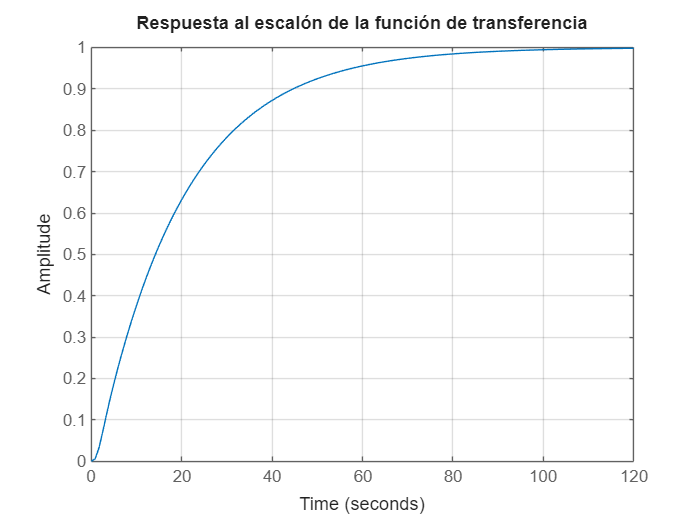


% Respuesta al escalón
figure;
step(sys);
title('Respuesta al escalón de la función de transferencia');
grid on;